## Problem 2

### Part (A)

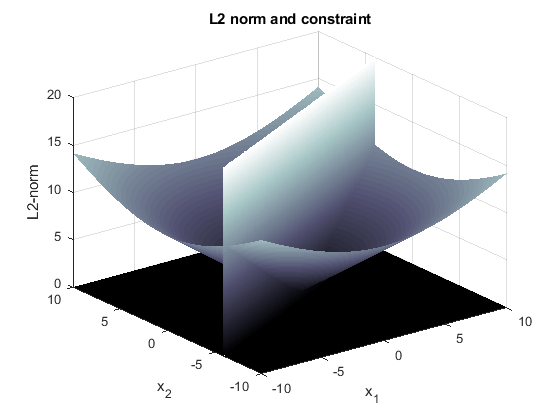

%% Setup
A = [1,-2];
b = 2;
x = (-10:.05:10)';
[xx,yy] = meshgrid(x,x); %treat as discretized x1,x2 variables

%% Plot L2 norm and constraint over span of x1,x2 variables
L2norm = sqrt((xx).^2+(yy).^2);
Const = zeros(size(xx));
for i = 1:length(xx)
    for j = 1:length(yy)
        z = [xx(i,j);yy(i,j)];
        Const(i,j) = abs(A*z-2)<0.1; %boolean
        Const = double(Const); %double
    end 
end 
figure; surf(xx,yy,L2norm); hold on
surf(xx,yy,Const*20);
shading interp; title('L2 norm and constraint'); xlabel('x_1'); ylabel('x_2'); zlabel('L2-norm')
colormap bone; hold off

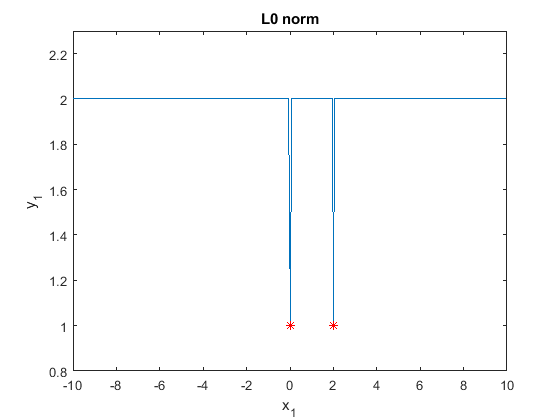

%% Constrain solutions to 1D
y = 0.5*x-1; %1D solution to linear equation
X = [x,y];

%% Find the L0 norm
X0 = X;
X0(X0~=0)=1; %turn nonzero values into 1's
L0 = abs(sum(X0,2));
[min0,ind0] = min(L0); %NOT THE ONLY MIN
figure; plot(x,L0); hold on; 
plot(0,1,'r*'); plot(2,1,'r*')
xlim([-10,10]); ylim([0.8,2.3]); hold off
title('L0 norm'); xlabel('x_1'); ylabel('y_1');

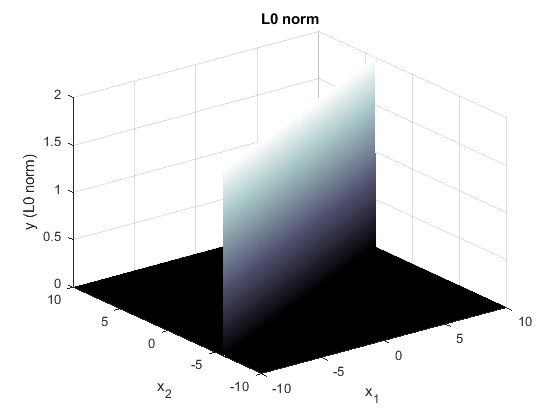


L0x = xx; L0y = yy;
L0x(abs(L0x)>0)=1; L0y(abs(L0y)>0)=1;
L0full = (L0x+L0y).*Const;
figure; surf(xx,yy,L0full); shading interp;
title('L0 norm'); xlabel('x_1'); ylabel('x_2'); zlabel('y (L0 norm)')
colormap bone; 

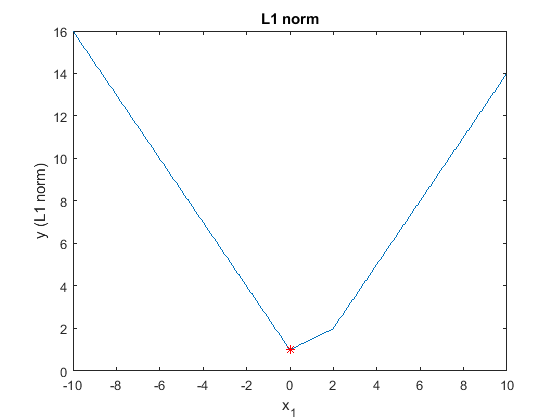


%% Find the L1 norm
X1 = X;
L1 = sum(abs(X1),2);
[min1,ind1] = min(L1);
figure; plot(x,L1); hold on;
plot(0,L1(201),'r*'); hold off
title('L1 norm'); xlabel('x_1'); ylabel('y (L1 norm)');

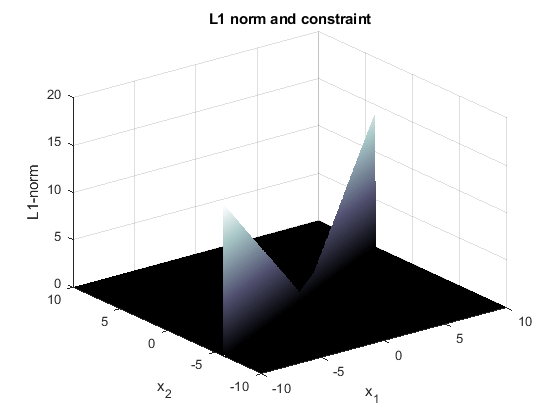


L1full = (abs(xx)+abs(yy)).*Const;
figure; surf(xx,yy,L1full);
shading interp; title('L1 norm and constraint'); xlabel('x_1'); ylabel('x_2'); zlabel('L1-norm')
colormap bone; hold off

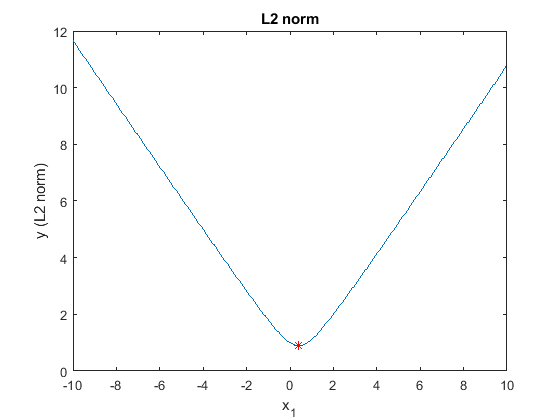


%% Find the L2 norm
X2 = X;
L2 = rssq(X2,2);
[min2,ind2] = min(L2);
figure; plot(x,L2); hold on
plot(x(209),L2(209),'r*'); hold off
title('L2 norm'); xlabel('x_1'); ylabel('y (L2 norm)');

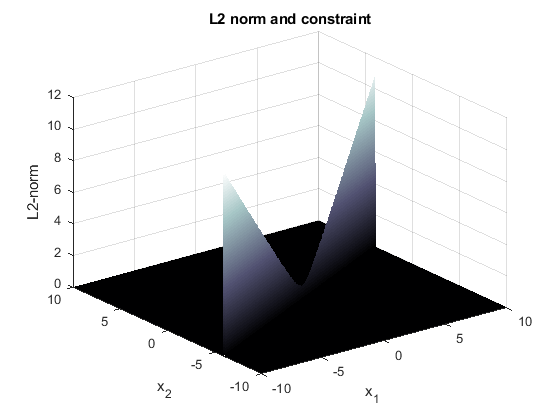


L2full = L2norm.*Const;
figure; surf(xx,yy,L2full);
shading interp; title('L2 norm and constraint'); xlabel('x_1'); ylabel('x_2'); zlabel('L2-norm')
colormap bone;

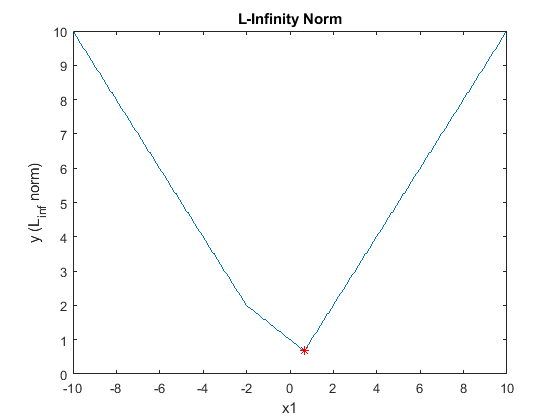


%% Find the L-infinity norm
X8 = X;
L8 = max(abs(X8),[],2);
[min8,ind8] = min(L8);
figure; plot(x,L8); hold on
plot(x(214),L8(214),'r*'); hold off
title('L-Infinity Norm');xlabel('x1'); ylabel('y (L_{inf} norm)')

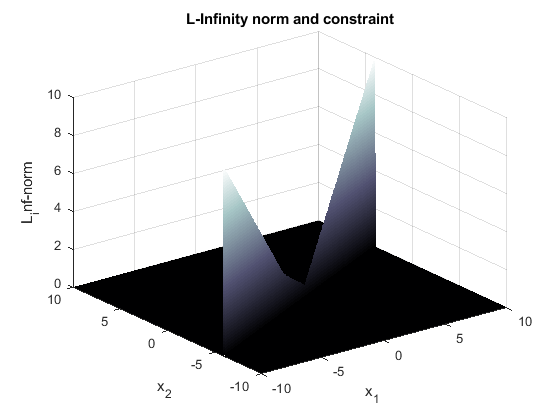


for i=1:length(xx)
    for j=1:length(yy)
        L8max = max(abs(xx),abs(yy));
    end
end
L8full = L8max.*Const;
figure; surf(xx,yy,L8full);
shading interp; title('L-Infinity norm and constraint'); xlabel('x_1'); ylabel('x_2'); zlabel('L_inf-norm')
colormap bone;